# **Question 1(c)**

#### **plot of sigma P**

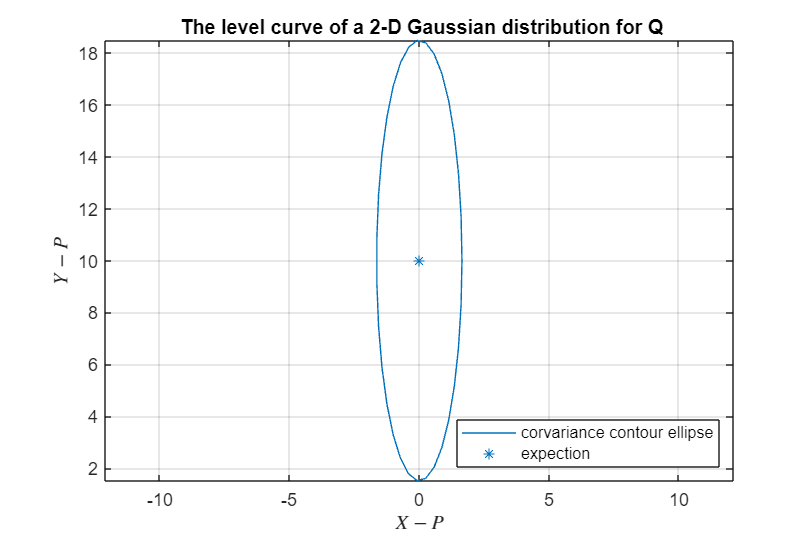

clear all
clc
mu_p=[0;10];sigma_p=[0.3 0;0 8];A=[1 0.5;0 1];b=zeros(2,1);

%Call your function.
xy_p = sigmaEllipse2D(mu_p, sigma_p);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_p(1,:), xy_p(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{P}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{P}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Q')
grid on ;
plot(mu_p(1), mu_p(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

#### plot of sigma P

[mu_z, sigma_z] = affineGaussianTransform(mu_p, sigma_p, A, b)

mu_z =      5
    10


sigma_z =     2.3000    4.0000
    4.0000    8.0000


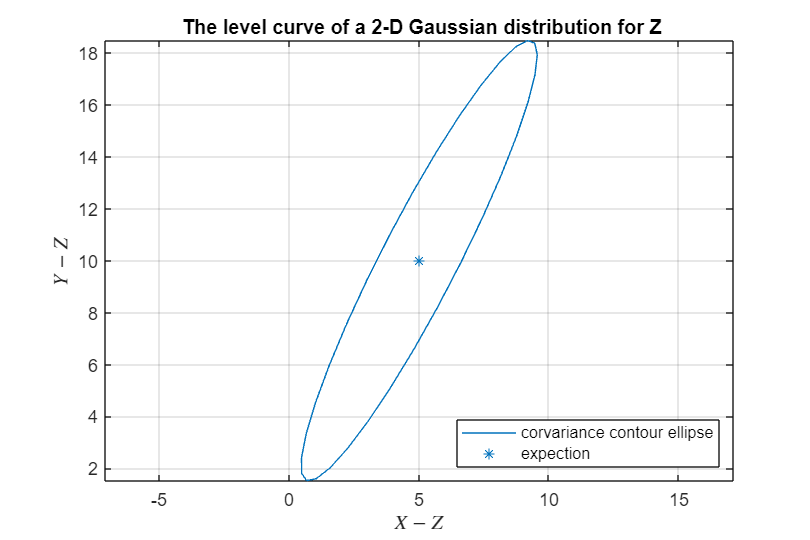

xy_z = sigmaEllipse2D(mu_z, sigma_z);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_z(1,:), xy_z(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{Z}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{Z}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Z')
grid on ;
plot(mu_z(1), mu_z(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

# Question2(a)


mu_x2=0;sigma_x2=2;
A2=3;b2=0;f=@(x)(3*x);N=10000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18



[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = 0.0180

sigma_z3 = 18.0170

y_z3 =     0.6686    2.9706   -2.1208   -0.6862    1.0372   -2.2794    4.2242    4.2895    0.4227   -3.3553  -13.6158    5.5661   -3.1238   -5.7156   -3.4807   -2.9327   -3.3854   -3.5102    1.3864    3.6780   -0.6863    0.3343    3.2423  -13.4814    4.4791   -0.1330   -3.8381   -7.2273    9.4778   -5.0145   -8.9358   -4.1271   -7.7139   -0.3334    4.3565    2.8866    8.9263   -0.6429    0.9500   -5.4650   -2.5505    8.7154   -3.3843   -2.4668   -2.6199    1.0835   -6.9884    7.1907   -5.3947    4.0055


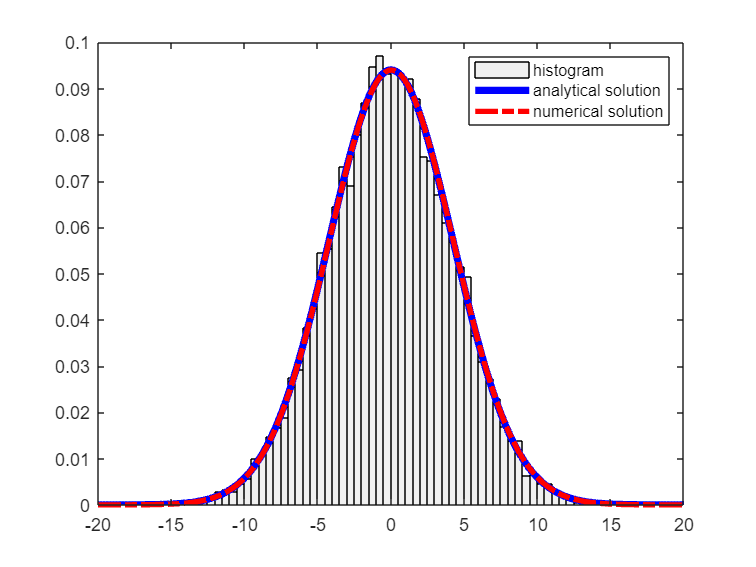

figure()
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')

# Question2(b)

f2=@(x)(x^3);N=100000;
[mu_z4, sigma_z4, y_z4] = approxGaussianTransform(mu_x2, sigma_x2, f2, N)

mu_z4 = 0.0143

sigma_z4 = 120.6930

y_z4 =     0.1496   -0.0107  -29.1901   -4.1727   -6.3940  -21.7632   -0.0002    4.4754  -20.4908   -0.1576   -6.4804   -0.0001   -9.4906    8.4283   11.3795    1.0116  -15.9307   -0.3569   -0.0144    0.1806    0.0711    0.0034    0.0191    0.0840    0.0108    0.0673   -0.2244    1.4108    0.3546    2.2395    0.0234    1.8385  -51.1599   -5.4302   -4.2504   -0.7661   -6.6596   -1.0126   -0.7533    1.2224    8.6602   -0.3245  -10.5676  -20.9938    0.8419    0.0097   28.3602   14.5575   -0.0000    2.7130


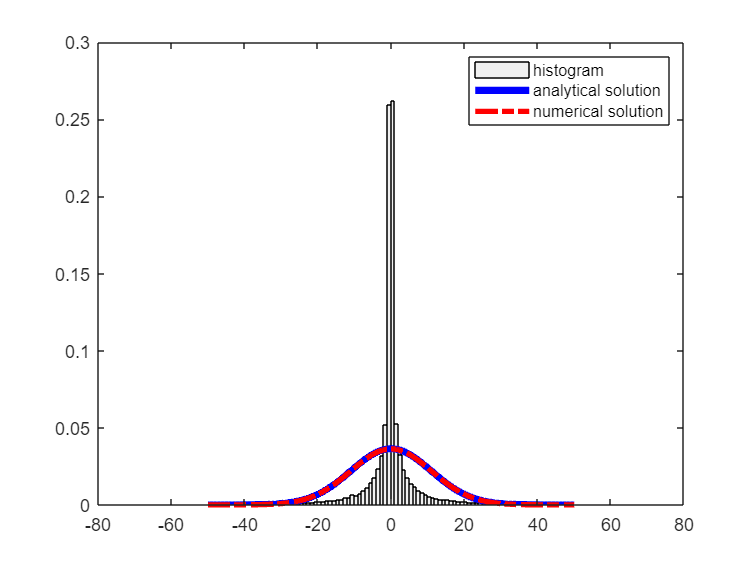

figure()
histogram(y_z4,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x1=[-50:0.1:50];
xlim([-80,80])
y=normpdf(x1,0,sqrt(120));
plot(x1,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x1,mu_z4,sqrt(sigma_z4));
plot(x1,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
%nonlinear transform, not a Gaussian
hold off

# Question3

# P(y)

clear all
N=100000;
H21=@(x)(4*x);%linear function
a=10;b=20;
x31=[-200:1:200];
%assume sigma_r^2=25
X_uni=a+(b-a)*rand(1,N)%get samples using uniform distribution

X_uni =    18.2142   14.6123   13.8483   10.2634   13.4392   11.6184   11.0804   19.4432   17.5702   14.6733   18.9014   18.9427   19.8770   12.2908   14.0192   18.6205   12.5283   19.3581   14.0703   15.4672   16.0435   12.2093   19.3218   10.0146   16.1986   13.8024   16.8219   19.3579   13.0337   13.1712   14.0716   18.7878   19.3833   11.8939   13.1076   15.7701   17.8791   13.8672   16.0884   11.9476   13.8902   10.9285   10.0714   10.9801   11.8716   10.0100   10.1675   15.4883   14.2868   15.2784


r=mvnrnd(0, 25,N)'%get samples using normal distribution

r =     3.1107   -7.4629    4.3678    2.8475    0.7266   -0.4703    0.1495   -2.9852    7.1486   -5.2346    4.8710   -6.7090   -4.2151    2.0008   -7.5877    0.8976    2.7775   -1.4568    2.7977   -0.7881  -10.1859    4.7545   -0.7334   -2.4038    2.3749  -11.3005    5.8562    6.3721   -5.3200   -3.5868   -3.9396   -8.0586    1.6600   -2.5317   -3.5196    8.7148    0.6759   -2.3076    1.7726   -5.6686    0.6961    4.1043    0.3894    9.1259    5.6861   -4.3830    5.0847   -8.1726   -3.8855   -6.8182


% X_uni=unifpdf(x31,-20,20)
ys_3111=[];
for i=1:N
    ys_3111=[ys_3111,H21(X_uni(:,i))];%if it is uniform
end
ys31=[1 1]*[ys_3111;r];
histogram(ys31,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
% figure()
% plot(normys31)
hold on
y=[0:0.1:100]

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


func=-(erf(8-y/5)+erf((y-80)/5))/(80)

func =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


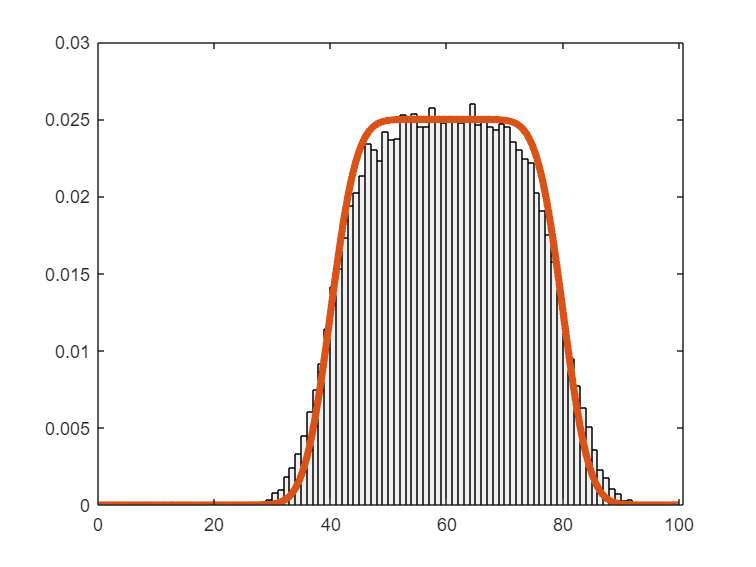

plot(y,func,'LineWidth',4)
hold off

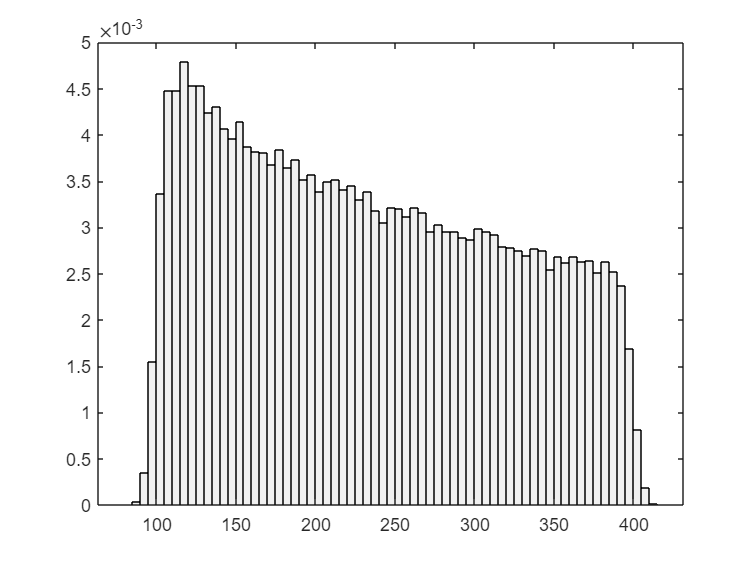

%Integrate[1/10*(1/(sqrt(2*pi*5^2)))*exp(-(y-x^2)^2/2*5^2),{x,10,20}]
H31=@(x)(x^2);%nonlinear function
ys_3222=[];
for i=1:N
    ys_3222=[ys_3222,H31(X_uni(:,i))];%if it is uniform
end
ys32=[1 1]*[ys_3222;r];
histogram(ys32,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold off

X_normal=mvnrnd(0, 25,N)'

X_normal =    -2.4620    0.6515   -1.2493    4.5179    3.8106   -0.8922    4.4841   -5.0804    0.4500   -3.0702    1.2443    5.5007    0.1169   -4.7970    3.7978   -3.4620   -0.7955   -1.7739    4.7083    5.9799   -3.3611    1.8155    4.4565    6.8104  -11.9992   -0.7144    0.3012    5.0523    0.2548   -2.4096    4.3279   -5.9309    2.3172    5.5922   -6.2966   -7.6704    0.9278   -3.5246   -2.5674    2.7829   -1.8983    6.4005   12.5117   -1.5465   -3.4939   -5.6382   -9.6255   -2.8516    5.1243   -0.6977


ys_3333=[];
for i=1:N
    ys_3333=[ys_3333,H21(X_normal(:,i))];%if it is uniform
end
ys33=[1 1]*[ys_3333;r];
figure()
histogram(ys33,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normal3=[-100:0.1:100];
y=normpdf(x_normal3,0,sqrt(425))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


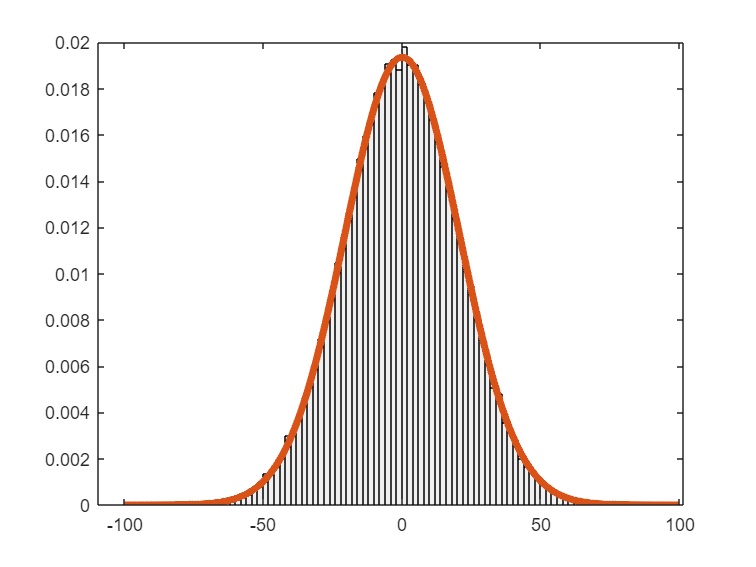

plot(x_normal3,y,'LineWidth',4)
hold off

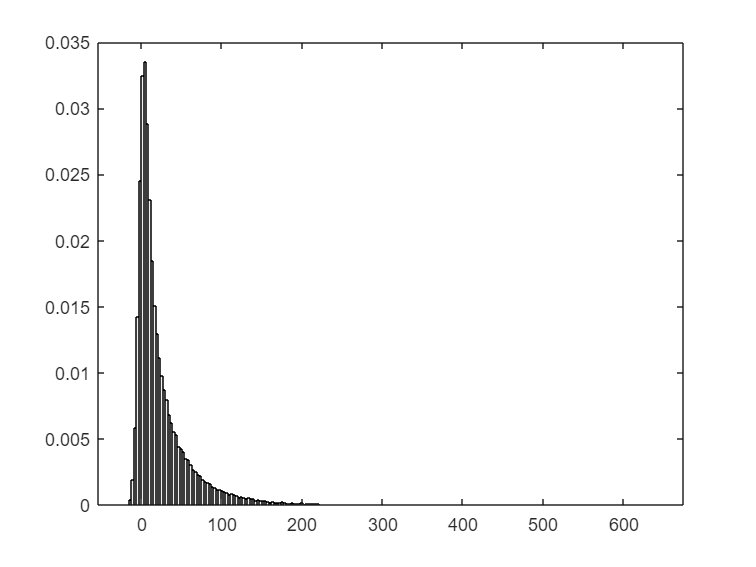

ys_3444=[];
for i=1:N
    ys_3444=[ys_3444,H31(X_normal(:,i))];%if it is uniform
end
ys34=[1 1]*[ys_3444;r];
histogram(ys34,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

# P(y|x)

%%%%%%uniform linear
X_rand=a+(b-a)*rand;
y_31pyx=r+H21(X_rand);
figure()
histogram(y_31pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normalyx1=[0:0.1:95];
y=normpdf(x_normalyx1,H21(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


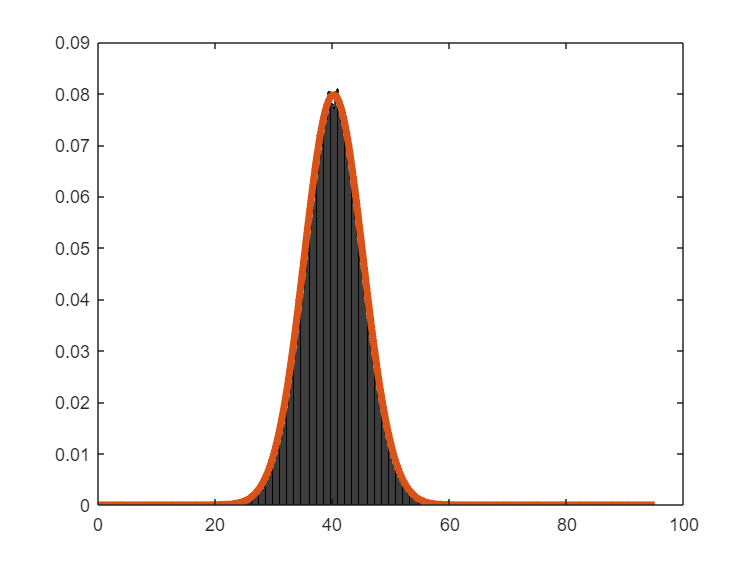

plot(x_normalyx1,y,'LineWidth',4)
hold off

%%%%%%uniform nonlinear
y_32pyx=r+H31(X_rand);
figure()
histogram(y_32pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx2=[100:0.1:250];
y=normpdf(x_normalyx2,H31(X_rand),sqrt(25))

y =     0.0782    0.0785    0.0788    0.0790    0.0792    0.0794    0.0795    0.0797    0.0797    0.0798    0.0798    0.0798    0.0797    0.0796    0.0795    0.0794    0.0792    0.0790    0.0787    0.0785    0.0782    0.0778    0.0775    0.0771    0.0767    0.0762    0.0758    0.0753    0.0747    0.0742    0.0736    0.0730    0.0724    0.0717    0.0710    0.0703    0.0696    0.0689    0.0681    0.0673    0.0666    0.0657    0.0649    0.0641    0.0632    0.0624    0.0615    0.0606    0.0597    0.0588


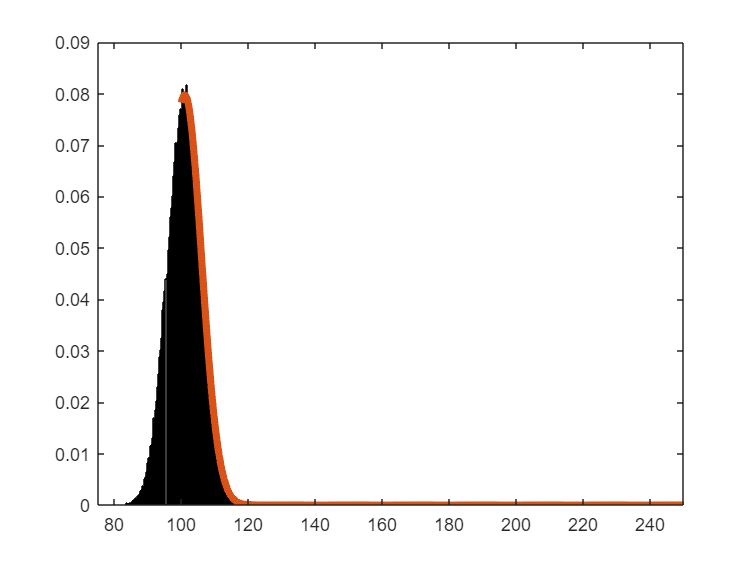

hold on
plot(x_normalyx2,y,'LineWidth',4)
hold off

X_randn=mvnrnd(0, 25,1);

%%%%%%guassian linear
y_33pyx=r+H21(X_randn);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx3=[-50:0.1:50];
hold on
y=normpdf(x_normalyx3,H21(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


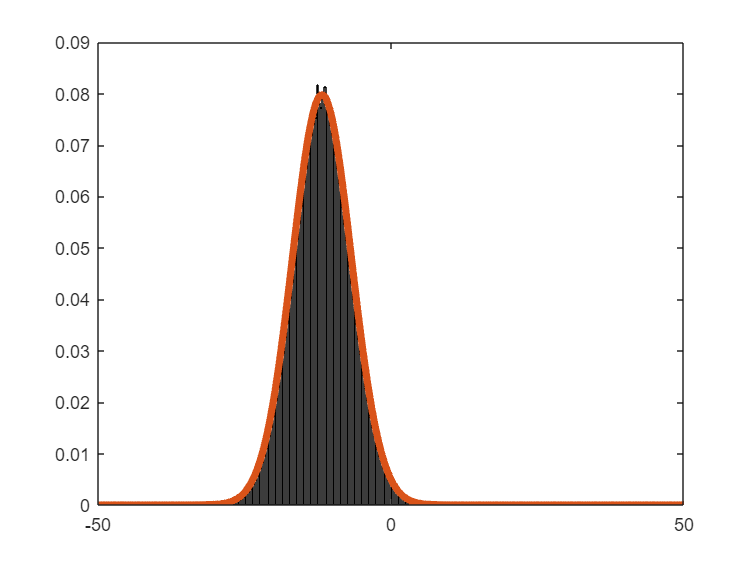

plot(x_normalyx3,y,'LineWidth',4)
hold off

%%%%%%guassian nonlinear
y_33pyx=r+H31(X_randn);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx4=[-50:0.1:50];

hold on
y=normpdf(x_normalyx4,H31(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


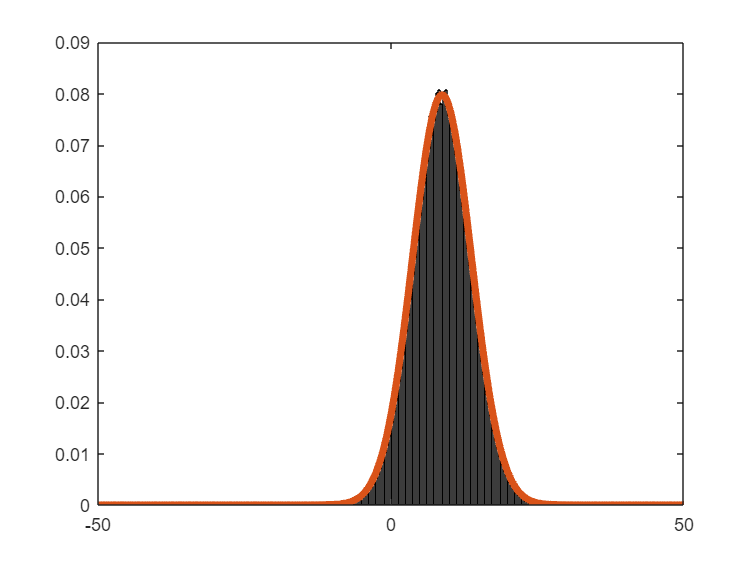

plot(x_normalyx4,y,'LineWidth',4)
hold off

# Question4

clear all
sigma41=0.5^2;
N=100000;
x41=[-4:0.1:4];
y41=0.5*normpdf(x41,-1,sqrt(sigma41))+0.5*normpdf(x41,1,sqrt(sigma41));
figure()
plot(x41,y41,'LineWidth',4);
hold on
w=(mvnrnd(0,sigma41,N))'

w =    -0.5768    0.1382    0.0284   -0.0469   -0.3940    0.8497    0.8850    0.0021    0.5397   -0.5394   -0.7736    0.7616    0.1249   -0.4213    0.1860    0.0363    0.2419    0.0685    0.3130    0.3968    0.2064    0.4088   -0.4238   -0.0066   -0.2730    0.6083   -0.4644   -0.5752   -0.4885    0.7846    0.3938   -0.5418    0.0385    0.0599   -0.2210   -0.0599   -0.1573   -1.1549   -0.2661    0.0544    0.9029   -0.7756   -0.3353    0.0423   -0.5359    0.3278    0.4016    0.3647   -0.7990    0.6399


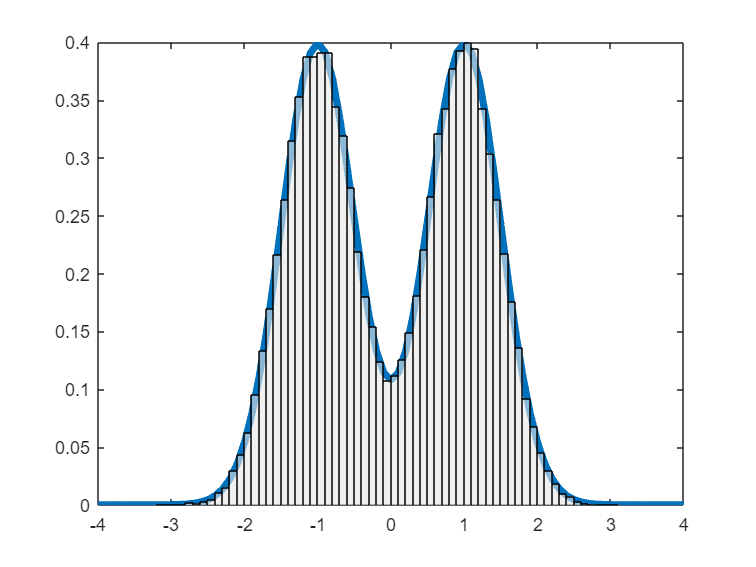

y42=[];
for i=1:N
    random_bit = randi([0, 1], 1, 1);
    if random_bit == 0
        theta = -1;
        y42=[y42 theta+w(i)];
    else
        theta = 1;
        y42=[y42 theta+w(i)];
    end
end
histogram(y42,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

hold off

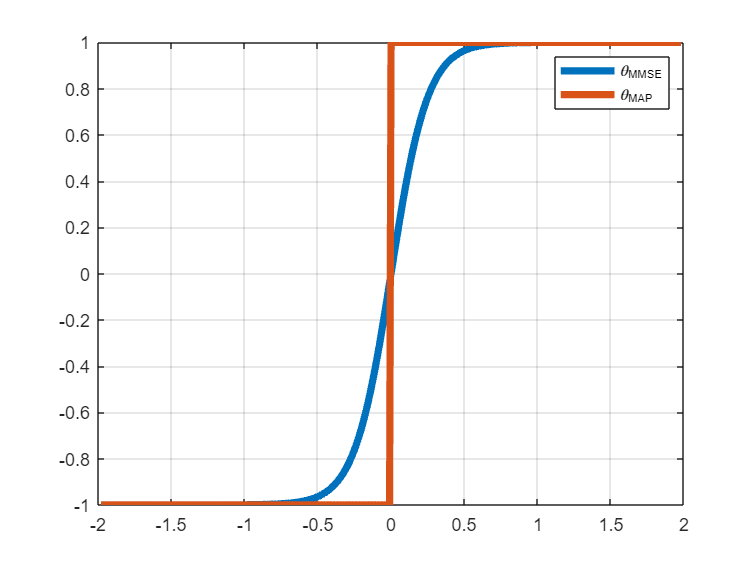


y47=[-1.98:0.01:1.98];
theta_MMSE=[];
theta_MAP=[];

for i=1:size(y47,2)
    theta_MMSE=[theta_MMSE,(exp(-2*(y47(i)-1)^2)-exp(-2*(y47(i)+1)^2))/(exp(-2*(y47(i)-1)^2)+exp(-2*(y47(i)+1)^2))];
    if exp(4*y47(i))<1
        theta_MAP=[theta_MAP,-1];
    else
        theta_MAP=[theta_MAP,1];
    end
end
figure()
plot(y47,theta_MMSE,'LineWidth',4)
hold on
plot(y47,theta_MAP,'LineWidth',4)
grid on
legend('\theta_{MMSE}','\theta_{MAP}','intepreter','latex')

# function

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end
phi=linspace(0,2*pi,npoints);
xy=zeros(2,npoints);
n=0;
for i=1:npoints
    xy(:,i)=mu+level*sqrtm(Sigma)*[cos(phi(:,i));sin(phi(:,i))];
end
%Your code here
%disp(size(xy,2))
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b)
%affineTransformGauss calculates the mean and covariance of y, the 
%transformed variable, exactly when the function, f, is defined as 
%y = f(x) = Ax + b, where A is a matrix, b is a vector of the same 
%dimensions as y, and x is a Gaussian random variable.
%
%Input
%   MU_X        [n x 1] Expected value of x.
%   SIGMA_X     [n x n] Covariance of x.
%   A           [m x n] Linear transform matrix.
%   B           [m x 1] Constant part of the affine transformation.
%
%Output
%   MU_Y        [m x 1] Expected value of y.
%   SIGMA_Y     [m x m] Covariance of y.

%Your code here
    mu_y=A*mu_x+b;%mu_z=E{AX+BY}=A*mu_x+B*mu_y
    Sigma_y=A*Sigma_x*A';%Sigma_z=Cov{AX+BY}=Cov{Ax}+Cov{By}
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y, y_s] = approxGaussianTransform(mu_x, Sigma_x, f, N)
%approxGaussianTransform takes a Gaussian density and a transformation 
%function and calculates the mean and covariance of the transformed density.
%
%Inputs
%   MU_X        [m x 1] Expected value of x.
%   SIGMA_X     [m x m] Covariance of x.
%   F           [Function handle] Function which maps a [m x 1] dimensional
%               vector into another vector of size [n x 1].
%   N           Number of samples to draw. Default = 5000.
%
%Output
%   MU_Y        [n x 1] Approximated mean of y.
%   SIGMA_Y     [n x n] Approximated covariance of y.
%   ys          [n x N] Samples propagated through f


if nargin < 4
    N = 5000;
end

%Your code here
X = mvnrnd(mu_x, Sigma_x,N)';
% disp(size(X,1))
mu=zeros(size(mu_x,1),1);
y_s=[];
for i=1:N
    y_s=[y_s,f(X(:,i))];
end
mu_y=mean(y_s,2);
Sigma_y=(y_s-mu_y)*(y_s-mu_y)'/(N-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu, Sigma] = jointGaussian(mu_x, sigma2_x, sigma2_r)
%jointGaussian calculates the joint Gaussian density as defined
%in problem 1.3a. 
%
%Input
%   MU_X        Expected value of x
%   SIGMA2_X    Covariance of x
%   SIGMA2_R    Covariance of the noise r
%
%Output
%   MU          Mean of joint density 
%   SIGMA       Covariance of joint density
A=[1 0;1 1];b=zeros(2,1);
mu_x=[mu_x,0]';
Sigma_x=[sigma2_x,0;0,sigma2_r];
[mu, Sigma] = affineGaussianTransform(mu_x, Sigma_x, A, b);
%Your code here
end